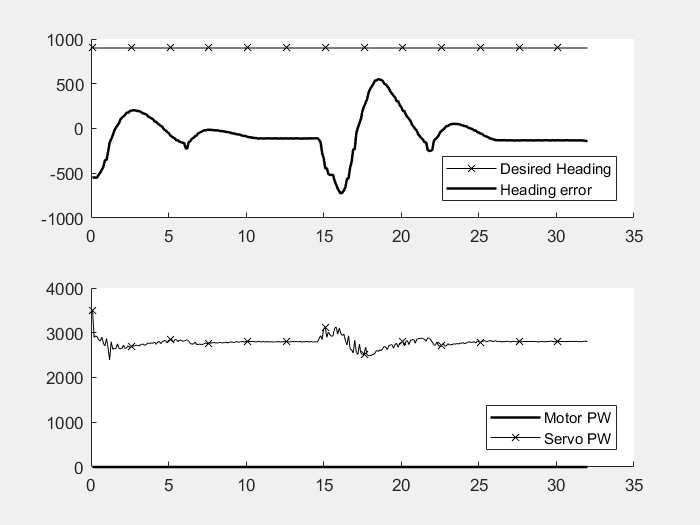

current_data = data006;
time = .1*(1:size(current_data,1)); %coefficient reflects
                                    %each data point is 100 ms

close all
figure(1)
set(gcf,'Visible','on') %Automatically pop out the figure
clf
subplot(2,1,1)
hold on
plot(time,current_data(:,1),'x-k','MarkerIndices',(1:25:size(current_data,1)))
plot(time,current_data(:,2),'-k','LineWidth',1.5)
legend('Desired Heading','Heading error', 'Location', 'southeast')

subplot(2,1,2)
hold on
plot(time,current_data(:,5),'-k','LineWidth',1.5)
plot(time,current_data(:,6),'x-k','MarkerIndices',(1:25:size(current_data,1)))
legend('Motor PW','Servo PW','Location','southeast')

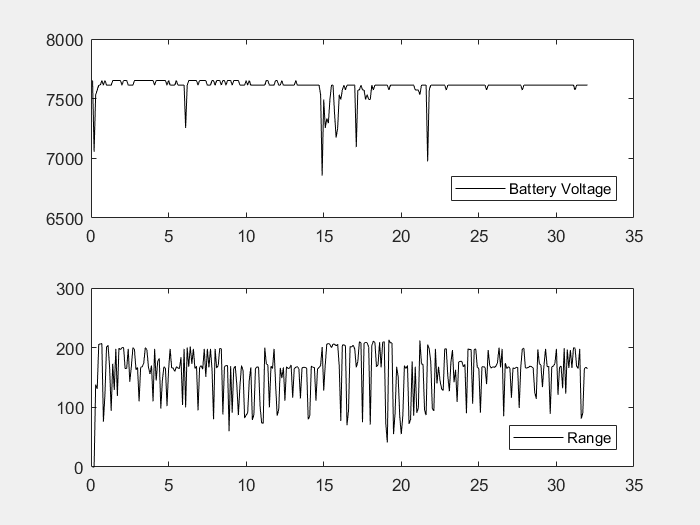


%----------------------------------------------------------------
figure(2)
set(gcf,'Visible','on') %Automatically pop out the figure
clf

subplot(2,1,1)
plot(time,current_data(:,4),'-k')
legend('Battery Voltage','Location','southeast')

subplot(2,1,2)
plot(time,current_data(:,3),'-k')
legend('Range','Location','southeast')
ylim([0 300])